# Example how to use MYWCORR code 

# (weighted norm of cross-correlation)

## Introduction

This script tests timeshifts estimation procedure with weighted norm of correlation

See files in library MLIB/BASIC fitcorr.m mywcorr.m

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 29th November 2016

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;


**NOTE**

Everywhere in this code dt is the difference between first break times of monitor and baseline:

% dt = Fb_m - Fb_b

## Define input parameters

Gnt = 1001;                 % Number of samples in the trace
Gdt = 0.001;                % Sample interval in sec
noiseamp = 0.05;            % Amplitude of noise 
fpeak = 10;                 % Peak frequency

## Create synthetic traces

pr = pi*rand(1,1000);
delta = zeros(1,1000); 

tic
for k=1:1000
    btrace = zeros(1, Gnt);
    mtrace = zeros(1, Gnt);
  
    t = 0:0.001:0.3;
    wt = ricker(fpeak,t); 
 
    btrace(350:650) = wt;
    mtrace(450:750) = wt; 
    
    % add phase rotation
    phaserotation = pr(k); 
    mtrace = add_phase_rotation(mtrace,phaserotation); 
    
    % add noise
    btrace = btrace + noiseamp*(rand(1, Gnt)-0.5);
    mtrace = mtrace + noiseamp*(rand(1, Gnt)-0.5);
    
    % estimate phase shift
    [dt, corr] = mywcorr(btrace, mtrace, fpeak, Gdt);

    % true phase shift is equal 0.1 sec
    delta(k) = dt - 0.1;
end
toc

Elapsed time is 0.513692 seconds.



disp(['Mean value over 1 000 experiments: ' num2str(mean(delta)*1000) ' msec']);       % should be about zero

Mean value over 1 000 experiments: 0.016685 msec


disp(['Standard deviation is equal: ' num2str(std(delta)*1000) ' msec']);               % idea about dispersion

Standard deviation is equal: 0.27173 msec


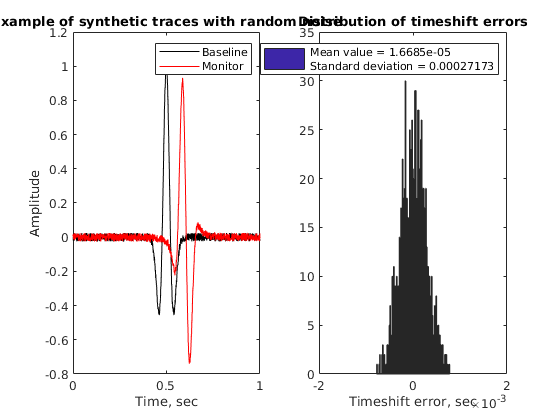


% Display delta
subplot(1,2,2)
hist(delta, 100);                        
xlabel('Timeshift error, sec')
axis([-0.002 0.002 0 35])
legend([' Mean value = ' num2str(mean(delta))  ' \newline Standard deviation = ' num2str(std(delta))]);
title('Distribution of timeshift errors')

% Display traces
subplot(1,2,1)
Gtt = (0:Gnt-1)*Gdt;
plot(Gtt, btrace, 'black');
hold on
plot(Gtt, mtrace, 'red');
xlabel('Time, sec');
ylabel('Amplitude');
title('Example of synthetic traces with random noise');
legend('Baseline', 'Monitor')